## Définition des variables

Dans cette section nous allons définire les variables qui vons nous être utile pour la modéliasation. 

### Variable pour les degrées de libertés (DDL)

le tableau suivant utilise la notation définie par SNAME(1950).

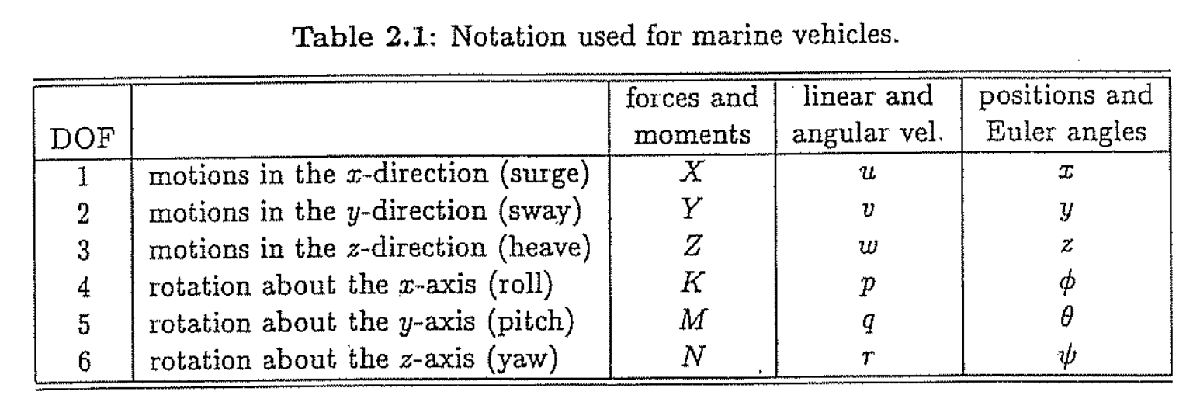

Vu que nous ne voulons utiliser les quaternions, nous n'allons pas définir les angle d'euler

  sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


% Définire Les forces et momments
    syms X Y Z K M N

% Définire les vitesse linéaire et angulaire
    syms u v w p q r

% Définire Les position linéaire
    syms x y z
    

### Variables pour le quaternions

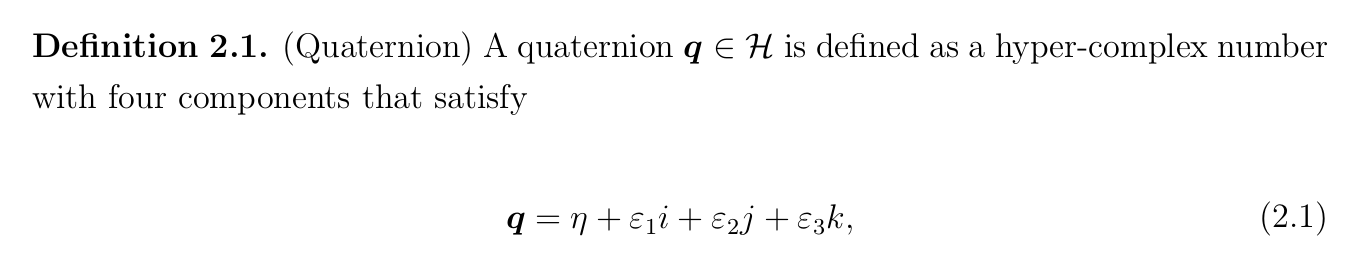

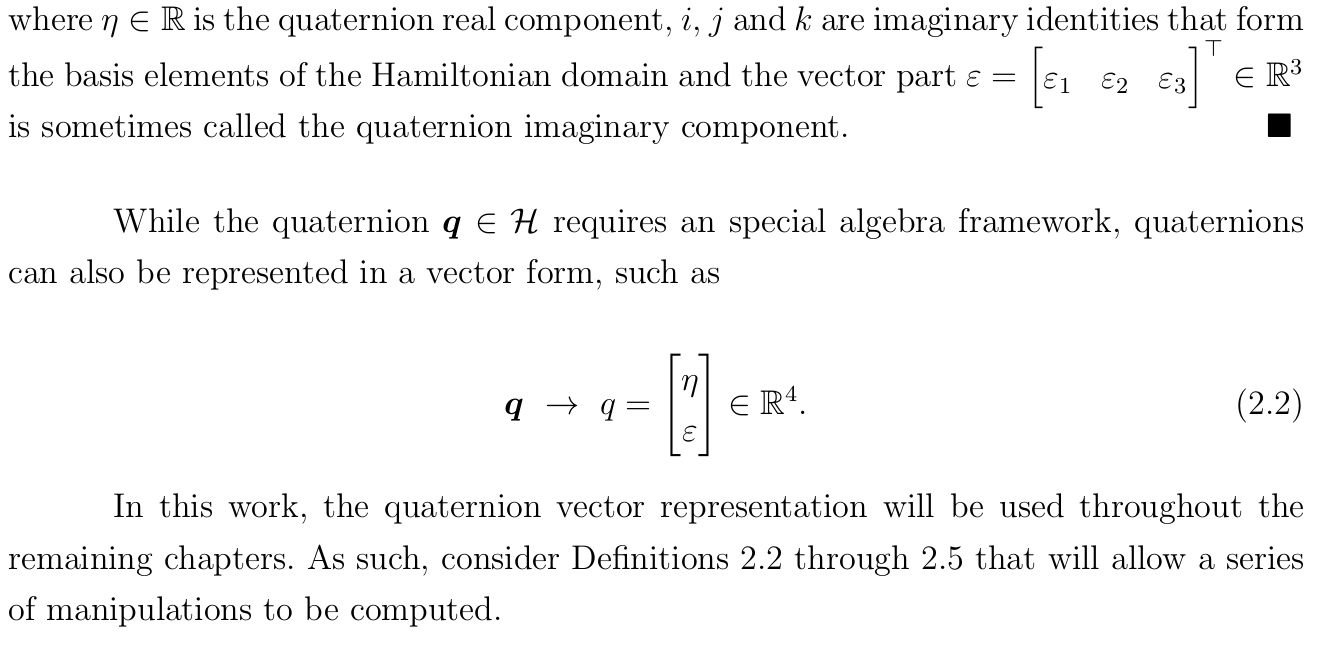


    % Définire La partie sclaire
        syms eta;
    % Définire La partie vectoriel
        syms('epsilon',[3,1]);
    
    % defenire le quaternion
        
    e=[eta; epsilon]

$$e = \left[\begin{array}{c} \eta \\ \epsilon_{1}\\ \epsilon_{2}\\ \epsilon_{3} \end{array}\right]$$

### Constante du modèle physique

% distance truster x y z selon centre geommétrique (Constantes)
% D14 distance thruster 1 a 4. (Constantes)
% D58 distance thruster 5 a 8. (Constantes)
% a14 angle thruster 1 a 4. (Constantes)
% dz distance entre les increments sur le frame. (Constantes)
% PZ position des truster sur le frame. (Constantes)
    syms('D14',[1 3]); syms('D58',[1 3]) ; syms a14 dz ; syms ('PZ',[1,4]);

% masse, volume du prototype et hauteur sub (Constantes)
    syms mass volume height

% coefficient de drag (Constantes)
    syms ('CD(x)', [1, 6]);

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g


### Grouper les variables

Nous allons par la suite regroper les variables

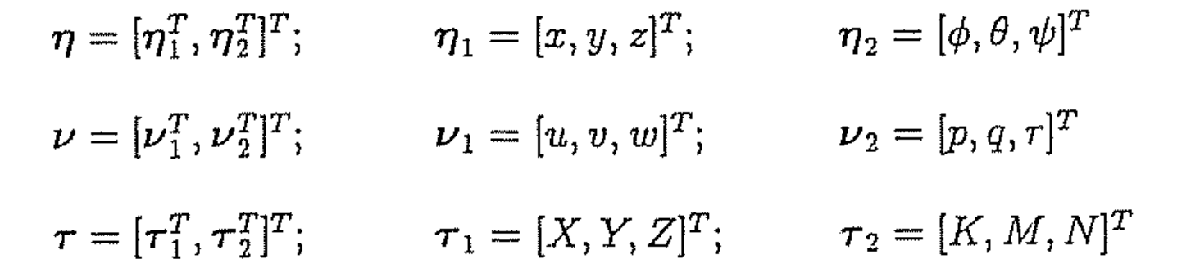

% Position et Orientation
    
    n1= [x,y,z].';
    Ne=[n1;e]

$$Ne = \left[\begin{array}{c} x\\ y\\ z\\ \eta \\ \epsilon_{1}\\ \epsilon_{2}\\ \epsilon_{3} \end{array}\right]$$

%Vitesse
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]

$$V = \left[\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r \end{array}\right]$$

## Équoition cinématique du mouvement

### Transformation de la vitesse linéaire

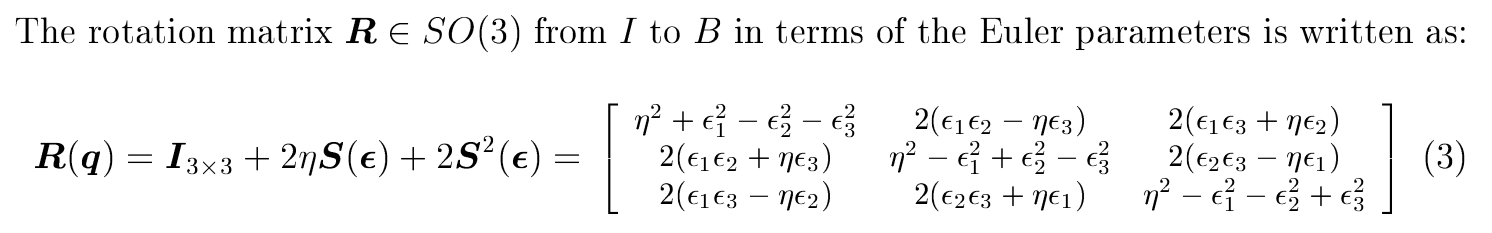

    % Équation 3
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2

$$E1 = \left[\begin{array}{ccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 \end{array}\right]$$

    
    % equation 2.24 (Fossen)
    EE1=[(eta^2-epsilon.'*epsilon)*eye(3)+2*epsilon*epsilon.'-2*eta*skew(epsilon)].'

$$EE1 = \left[\begin{array}{ccc} {\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -{\epsilon_{1}}^{2}+{\epsilon_{2}}^{2}-{\epsilon_{3}}^{2}+\eta^{2} & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta \\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -{\epsilon_{1}}^{2}-{\epsilon_{2}}^{2}+{\epsilon_{3}}^{2}+\eta^{2} \end{array}\right]$$

### Transformation de la vitesse angulaire

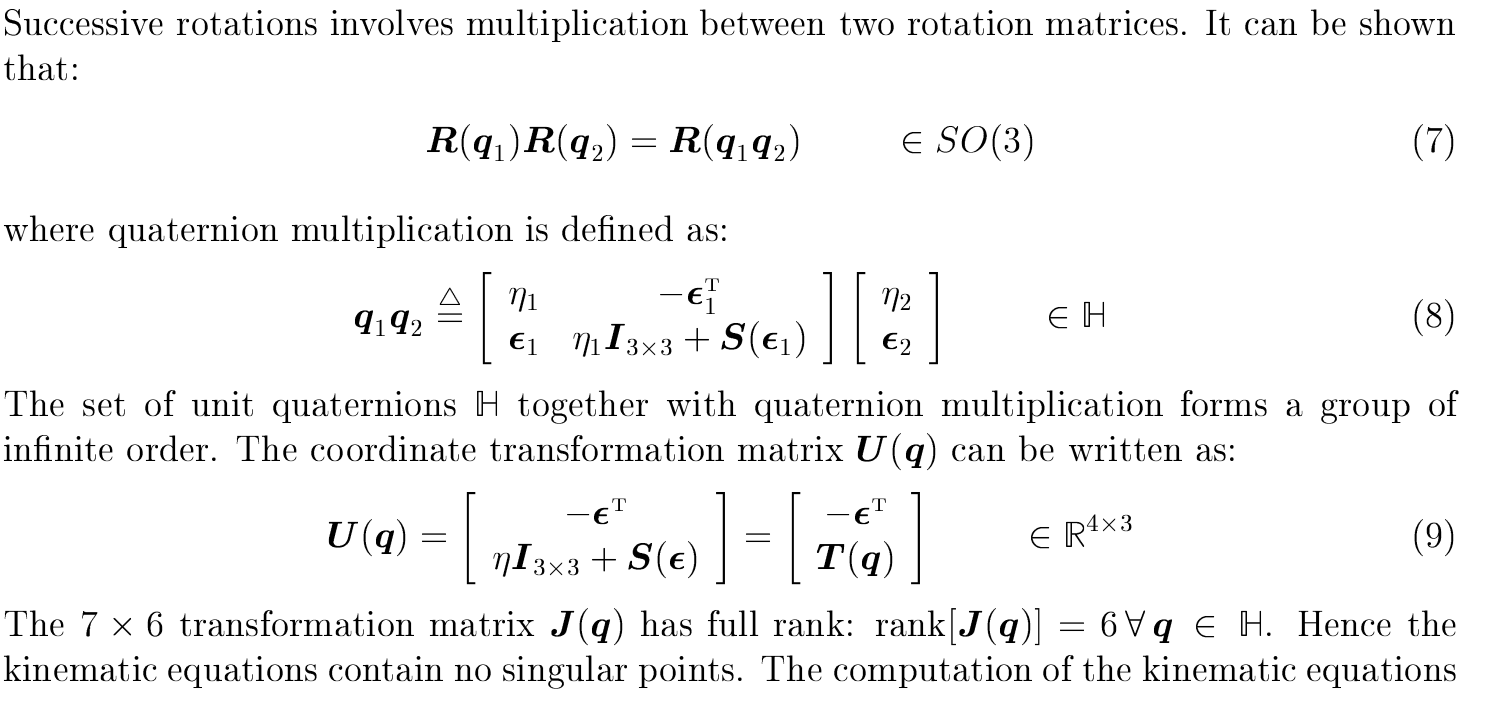

   E2=[-epsilon.';eta*eye(3)+skew(epsilon)]

$$E2 = \left[\begin{array}{ccc} -\epsilon_{1} & -\epsilon_{2} & -\epsilon_{3}\\ \eta & -\epsilon_{3} & \epsilon_{2}\\ \epsilon_{3} & \eta & -\epsilon_{1}\\ -\epsilon_{2} & \epsilon_{1} & \eta \end{array}\right]$$

### Matrice de transformation

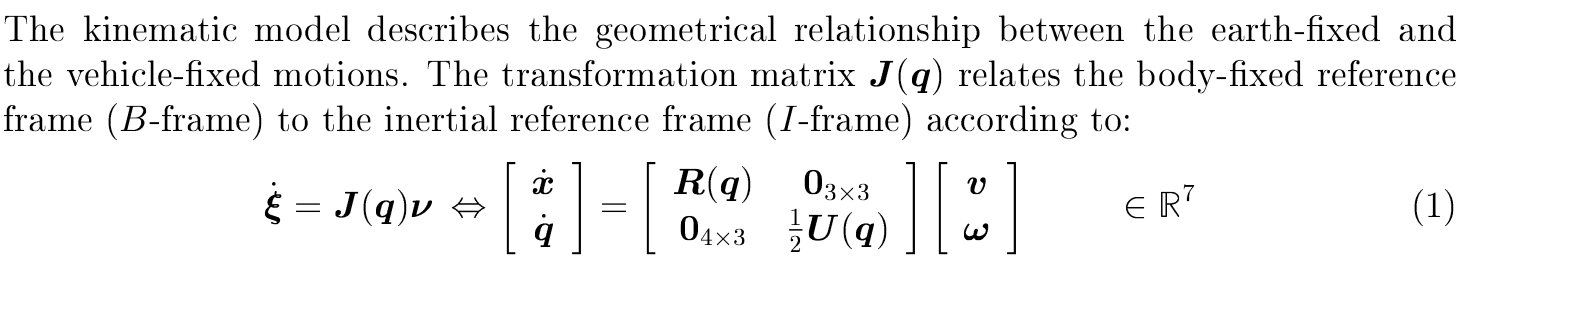

% Définir la matrice de transformation J(q)
   J=[E1,zeros(3,3);
   zeros(4,3),(1/2)*E2]

$$J = \left[\begin{array}{cccccc} -2\,{\epsilon_{2}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{1}\,\epsilon_{2}-2\,\epsilon_{3}\,\eta & 2\,\epsilon_{1}\,\epsilon_{3}+2\,\epsilon_{2}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{2}+2\,\epsilon_{3}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{3}}^{2}+1 & 2\,\epsilon_{2}\,\epsilon_{3}-2\,\epsilon_{1}\,\eta & 0 & 0 & 0\\ 2\,\epsilon_{1}\,\epsilon_{3}-2\,\epsilon_{2}\,\eta & 2\,\epsilon_{2}\,\epsilon_{3}+2\,\epsilon_{1}\,\eta & -2\,{\epsilon_{1}}^{2}-2\,{\epsilon_{2}}^{2}+1 & 0 & 0 & 0\\ 0 & 0 & 0 & -\frac{\epsilon_{1}}{2} & -\frac{\epsilon_{2}}{2} & -\frac{\epsilon_{3}}{2}\\ 0 & 0 & 0 & \frac{\eta }{2} & -\frac{\epsilon_{3}}{2} & \frac{\epsilon_{2}}{2}\\ 0 & 0 & 0 & \frac{\epsilon_{3}}{2} & \frac{\eta }{2} & -\frac{\epsilon_{1}}{2}\\ 0 & 0 & 0 & -\frac{\epsilon_{2}}{2} & \frac{\epsilon_{1}}{2} & \frac{\eta }{2} \end{array}\right]$$

## Équation dynamique d'un corps de Rigide

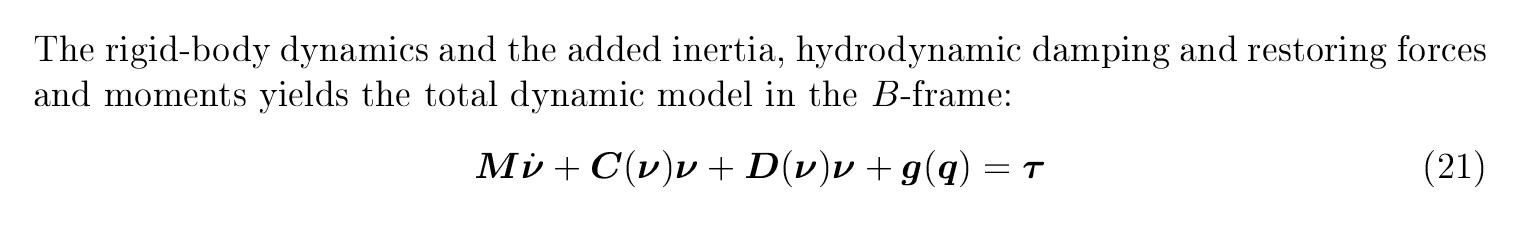

% Corp rigide
Mrb=[mass*eye(3),-mass*skew(RG);
     mass*skew(RG),I ]

$$Mrb = \left[\begin{array}{cccccc} \mathrm{mass} & 0 & 0 & 0 & {\mathrm{RG}}_{3}\,\mathrm{mass} & -{\mathrm{RG}}_{2}\,\mathrm{mass}\\ 0 & \mathrm{mass} & 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & {\mathrm{RG}}_{1}\,\mathrm{mass}\\ 0 & 0 & \mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & -{\mathrm{RG}}_{1}\,\mathrm{mass} & 0\\ 0 & -{\mathrm{RG}}_{3}\,\mathrm{mass} & {\mathrm{RG}}_{2}\,\mathrm{mass} & I_{1,1} & I_{1,2} & I_{1,3}\\ {\mathrm{RG}}_{3}\,\mathrm{mass} & 0 & -{\mathrm{RG}}_{1}\,\mathrm{mass} & I_{2,1} & I_{2,2} & I_{2,3}\\ -{\mathrm{RG}}_{2}\,\mathrm{mass} & {\mathrm{RG}}_{1}\,\mathrm{mass} & 0 & I_{3,1} & I_{3,2} & I_{3,3} \end{array}\right]$$

 
Crb= [zeros(3,3), -mass*skew(v1)- mass*skew(skew(v2)*RG);
     -mass*skew(v1)- mass*skew(skew(v2)*RG), skew(I*v2)+mass*skew(skew(v1)*RG)]

$$Crb = \begin{array}{l} \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v\\ 0 & 0 & 0 & -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4}\\ 0 & 0 & 0 & \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0\\ 0 & \mathrm{mass}\,w+\sigma_{6} & \sigma_{5}-\mathrm{mass}\,v & 0 & -I_{3,1}\,p-I_{3,2}\,q-I_{3,3}\,r-\sigma_{3} & I_{2,1}\,p+I_{2,2}\,q+I_{2,3}\,r-\sigma_{2}\\ -\mathrm{mass}\,w-\sigma_{6} & 0 & \mathrm{mass}\,u+\sigma_{4} & I_{3,1}\,p+I_{3,2}\,q+I_{3,3}\,r+\sigma_{3} & 0 & -I_{1,1}\,p-I_{1,2}\,q-I_{1,3}\,r-\sigma_{1}\\ \mathrm{mass}\,v-\sigma_{5} & -\mathrm{mass}\,u-\sigma_{4} & 0 & \sigma_{2}-I_{2,2}\,q-I_{2,3}\,r-I_{2,1}\,p & I_{1,1}\,p+I_{1,2}\,q+I_{1,3}\,r+\sigma_{1} & 0 \end{array}\right]\\ \mathrm{where}\\ \sigma_{1}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,v-{\mathrm{RG}}_{2}\,w\right)\\ \sigma_{2}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,u-{\mathrm{RG}}_{1}\,w\right)\\ \sigma_{3}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,u-{\mathrm{RG}}_{1}\,v\right)\\ \sigma_{4}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,q-{\mathrm{RG}}_{2}\,r\right)\\ \sigma_{5}=\mathrm{mass}\,\left({\mathrm{RG}}_{3}\,p-{\mathrm{RG}}_{1}\,r\right)\\ \sigma_{6}=\mathrm{mass}\,\left({\mathrm{RG}}_{2}\,p-{\mathrm{RG}}_{1}\,q\right) \end{array}$$

% Masse ajouté 

Ma1 = [zeros(3,3)];
Ma2 = [zeros(3,3)];
Ma3 = [zeros(3,3)];
Ma4 = [zeros(3,3)];

Ma = [Ma1,Ma2;
      Ma3,Ma4]

Ma =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


  
Ca =[zeros(3,3), -skew(Ma1*v1+Ma2*v2);
     -skew(Ma1*v1+Ma2*v2), -skew(Ma3*v1+Ma4*v2)]

$$Ca = \left[\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right]$$



M=Mrb+Ma

## Sous Fonction personalisé

Ici ce trouve nos fonction personalisé

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end